clear;clc;

load fisheriris;

## Data Processing

% Shuffle the dataset and pick 'split' number of samples for training
idx = randperm(size(meas,1));
X = meas(idx,:);
Y = zeros(size(species,1),1);
unq = unique(species);
for i = 1:size(unq,1)
    Y = Y + strcmp(unq{i}, species)*i;
end
Y = Y(idx,:);

split = 100;
X_train = X(1:split,:);
X_test = X(split+1:end,:);
Y_train = Y(1:split,:);
Y_test = Y(split+1:end,:);

D = size(X,2); K = size(unq,1);
Y_train_aug = zeros(size(X_train,1),K);
for k = 1:K
    Y_train_aug(:,k) = Y_train==k;
end

## Formulation

alpha = 1;
eta = 0.09;
epochs = 50;
predict = zeros(size(Y_test));
I = D;
H1 =  5;
H2 =  5;
O =  K;
w1 = randn(I,H1);
w2 = randn(H1,H2);
w3 = randn(H2,O);
E = zeros(1,epochs);
tic;
for t = 1:epochs
    for k = 1:length(X_train)
            % Rand3m dataset row selection parameter
            r = round(length(X_train).*rand(1,1));
            if r == 0
                r = r+1;
            end

            % r=k;
            
            % FORWARD PASS
            v1 = X_train(r,:)*w1;
            y1 = logsig(v1);
            v2 = y1*w2;
            y2 = logsig(v2);    
            v3 = y2*w3;
            y3 = logsig(v3);
            
            % ERROR CALCULATION
            e = Y_train_aug(r,:)-y3;
            
            % BACKWARD PASS
            d3 = dlogsig(v3,y3).*(e);
            d2 = dlogsig(v2,y2).*(d3*w3');
            d1 = dlogsig(v1,y1).*(d2*w2');
            

            w3 = alpha.*w3 + eta.*y2'*d3;
            w2 = alpha.*w2 + eta.*y1'*d2;
            w1 = alpha.*w1 + eta.*X_train(r,:)'*d1;
    end
    
    % Error after each epoch
    E(t) = sum(e.^2)/10;
    % Testing the X_test using the updated weight matrices
    v1T = X_test*w1;
    y1T = logsig(v1T);
    v2T = y1T*w2;
    y2T = logsig(v2T);    
    v3T = y2T*w3;
    y3T = logsig(v3T);
    
    % Predicting the values for each X_test input
    for z = 1:length(X_test)
        [val, col] = max(y3T(z,:));
        predict(z,:) = col;
    end

    % Calculating the Classification Rate in percentage
    CR(t) = (sum(predict==Y_test)/length(X_test))*100;
end

## Classification

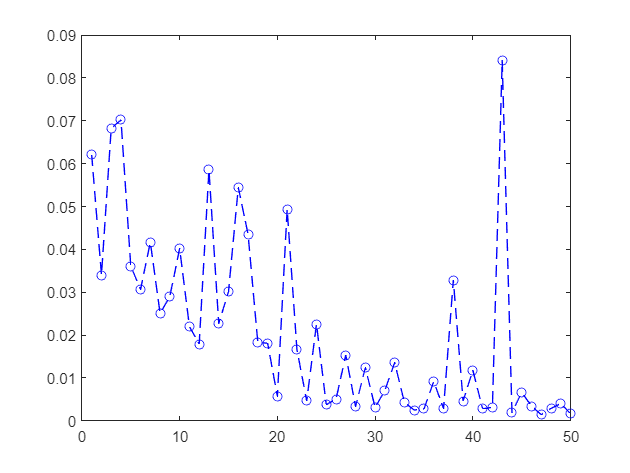

figure;
plot(1:epochs, E, 'b--o');

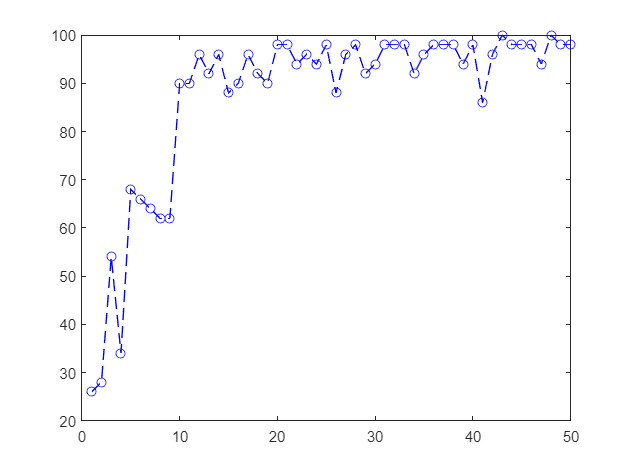

figure;
plot(1:epochs, CR, 'b--o');